# Condition Monitoring and Prognostics using Vibration Signals

load pdmBearingConditionMonitoringData.mat;
numSamples = length(data);
fs         = 20E3;       % sampling frequency

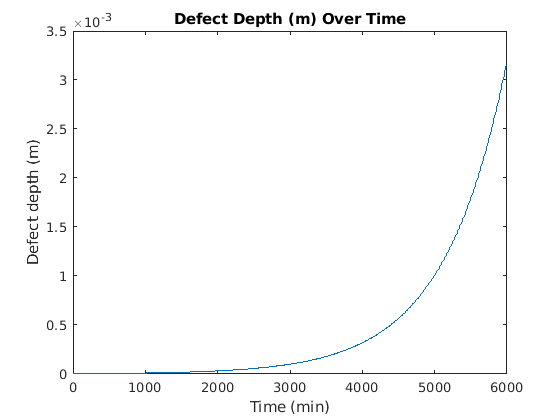

f1 = figure(1); clf;
plot(expTime,defectDepthVec);
xlabel('Time (min)');
ylabel('Defect depth (m)');
title('Defect Depth (m) Over Time');

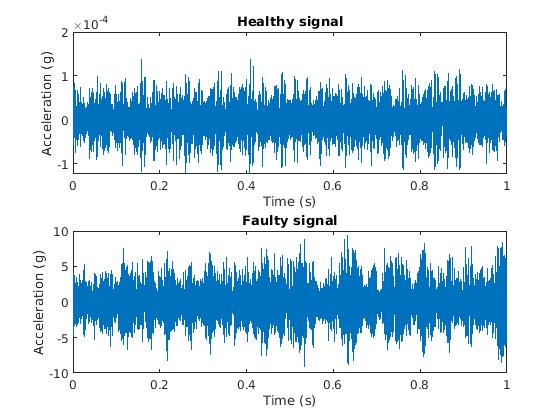

time = linspace(0,1,fs)';
f2   = figure(2); clf;

subplot(2,1,1);
plot(time,data{1}*.10197);
xlabel('Time (s)');
ylabel('Acceleration (g)');
title('Healthy signal');

subplot(2,1,2);
plot(time,data{end}*.10197);
xlabel('Time (s)');
ylabel('Acceleration (g)');
title('Faulty signal');

## Feature Extraction

- time domain features: rms, peak value, signal kurtosis, etc

- freq domain features: peak freq, mean freq, etc

Visualize signals with a spectrogram

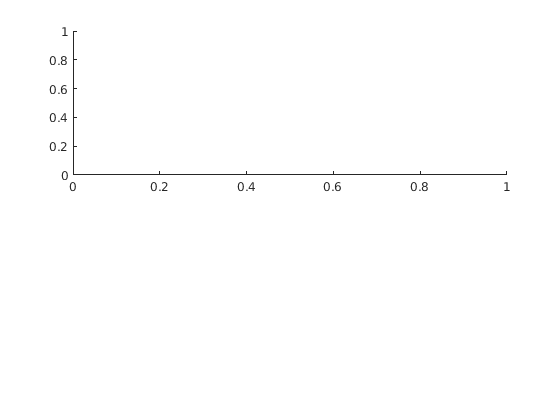

[~,healthy_freq_vector, healthy_time_vector, healthy_spectrogram] = spectrogram(data{1}, 500, 450, 512, fs);
[~,faulty_freq_vector, faulty_time_vector, faulty_spectrogram] = spectrogram(data{end}, 500, 450, 512, fs);

f3 = figure(3); clf;
subplot(211);

imagesc(healthy_time_vector, healthy_freq_vector, healthy_spectrogram);

Undefined function or variable 'imagsc'.

xlabel('Time (s)');
ylabel('Freq (Hz)');
title("Healthy Vibration Signal Spectrogram");
axis xy;

subplot(211);
imagesc(faulty_freq_vector, faulty_time_vector, faulty_spectrogra);
xlabel('Time (s)');
ylabel('Freq (Hz)');
title("Faulty Vibration Signal Spectrogram");
axis xy;